## Reproducible file accompanying the paper 

# OPTIMAL RECOVERY FROM INACCURATE DATA IN HILBERT SPACES: REGULARIZE, BUT WHAT OF THE PARAMETER?

by S. Foucart and C.Liao.

This reproducible was written by S. Foucart and C. Liao in November 2021.

CVX [2] is required to execute this reproducible

## L1: Locally optimal recovery in a complex Hilbert space with arbitrary observations

With $H$restricted to be a complex finite-dimensional Hilbert space, the Chebyshev center of the set $\{ f \in H: \|P_{\mathcal{V}^\perp} f \| \leq \varepsilon, \| \Lambda f - y \| \leq \eta \}$ is the solution $f_\tau$ to


$$\mathrm{\mathop{minimize}}\limits_{f \in H} \; (1-\tau) \|P_{\mathcal{V}^\perp} f\|^2 + \tau \| \Lambda f - y \|^2 $$
 

for the choice $\tau = d_\#/(c_\# + d_\# )$, where $c_\#,d_\#$ solve the semidefinite program


$$
\mathrm{minimize}\limits_{c,d,t \ge 0} \; \varepsilon^2 c + (\eta^2-\|y\|^2) d + t
 \quad \mbox{s.to} \quad 
c P_{\mathcal{V}^\perp} + d \Lambda^* \Lambda \succeq \mathrm{Id}
\quad \mbox{and} \quad  \left[\matrix{ c P_{\mathcal{V}^\perp} + d \Lambda^* \Lambda & | & -d \Lambda^* y 
\cr
\hline
-d(\Lambda^* y)^*  & | & t }\right]
\succeq 0.\\
$$


#### Problem setting

close all; clear;
% dimension of the ambiant Hilbert space
N = 50;         
% dimension of the approximation subspace
n = 15;                     
% subspace spanned by the columns of V
V = complex(randn(N,n),randn(N,n));
% projector onto the orthogonal complement of V
P1 = eye(N) - V*inv(V'*V)*V';         
% the approximability parameter
epsilon = 0.1;             
% number of observations
m = 25;                       
% the observation map (we use L instead of \Lambda)
L = complex(randn(m,N),randn(m,N));
% the uncertainty parameter
eta = 0.5;                    
% the original f and of its observation vector
aux = randn(N,1);
f = V*rand(n,1)+(epsilon/2)*aux/norm(aux);
% the inaccurate observations 
aux = randn(m,1);
y = L*f + (2*eta/3)*aux/norm(aux);

#### Computation of optimal parameters, Chebyshev centers, and local worst-case errors

% A MATLAB function named BE (for Beck and Eldar) is defined at the end of the file
% It returns the optimal paramater tau, the Chebyshev center, and the local worst-case error
[tau,cheb_center,local_wce] = BE(epsilon,eta,y,P1,L);
fprintf(['With H being a complex finite-dimensional Hilbert space, \n ' ...
'the optimal parameter tau is %.4f and \n the corresponding worst-case error is %.4f'],tau,local_wce)

With H being a complex finite-dimensional Hilbert space, 
 the optimal parameter tau is 0.0246 and 
 the corresponding worst-case error is 0.6318

#### Verification: the Chebyshev center does not depend  linearly on y 

The locally optimal recovery map ${\rm Cheb}
:\mathbb{R}^m\to H$ that sends $y\in\mathbb{R}^m$ to the Chebyshev center of the above set is not linear. 

To check it numerically, we illustrate that $2{\rm Cheb}(y) \neq {\rm Cheb}(2y).$

[~,cheb_center_2y,~] = BE(epsilon,eta,2*y,P1,L);
fprintf(['The norm of difference 2*Cheb(y)-Cheb(2*y) ' ...
    'is %.4f (not zero).'],norm(2*cheb_center-cheb_center_2y))

The norm of difference 2*Cheb(y)-Cheb(2*y) is 0.0007 (not zero).

## L2: Locally optimal recovery in real Hilbert space with orthonormal observations

Under the orthonormal observations assumption ($\Lambda\Lambda^*=\mathrm{Id}_{\mathbb{R}^m}$) but without the restriction that $H$is a complex Hilbert space, the Chebyshev center of the set $\{ f \in H: \|P_{\mathcal{V}^\perp} f \| \leq \epsilon, \| \Lambda f - y \| \leq \eta \}$ is the solution $f_{\tau_\#}$ to


$$\mathrm{\mathop{minimize}}\limits_{f \in H} \; (1-\tau_\#) \|P_{\mathcal{V}^\perp} f\|^2 + \tau_\# \| \Lambda f - y \|^2 $$
 

for the choice $\tau_\#$ of parameter $\tau$ between $1/2$ and $\varepsilon/(\varepsilon+\eta)$ that satisfies

$\lambda_{\min} ((1-\tau)P_{\mathcal{V}^\perp} + \tau \Lambda^* \Lambda)
= \frac{(1-\tau)^2 \epsilon^2 - \tau^2 \eta^2}{(1-\tau) \epsilon^2 - \tau \eta^2 + (1-\tau) \tau (1-2 \tau)  \delta^2}$,

where $\delta$ is precomputed as $\delta = \min\{ \|P_{\mathcal{V}^\perp}f\|: \Lambda f = y \} = \min \{ \|\Lambda f - y\|: f \in \mathcal{V} \}$.

With $\lambda_\# := \lambda_\min((1-\tau_\#)P_{\mathcal{V}^\perp}+\tau_\#\Lambda^*\Lambda)$, the squared Chebyshev radius (squared local worst-case error) is 

$\frac{1-\tau_\#}{\lambda_\#}\epsilon^2 + \frac{\tau_\#}{\lambda_\#}\eta^2 - \frac{(1-\tau_\#)\tau_\#}{\lambda_\#}\delta^2$.

#### Problem setting

We adopt the same problem setting as before, with the difference that the orthonormal observation assumption is in effect here.

close all; clear;
N = 50;         
n = 15;
V = rand(N,n);             
epsilon = 0.5;             
m = 25;                     
L = randn(m,N);            
L = (sqrtm(L*L'))\L;       % so that L satisfies L*L'=I
eta = 0.2;                 
aux = randn(N,1);
f = V*rand(n,1)+(eps/2)*aux/norm(aux);
aux = randn(m,1);
y = L*f + (2*eta/3)*aux/norm(aux);

#### Some useful objects

P1 = eye(N) - V*inv(V'*V)*V';  % orthogonal projector onto the orthogonal complement of V
P2 = L'*L;                     % orthogonal projector onto the range of L'
C = L*V;                       % cross-gramian (see the appendix)
b = (C'*C)\(C'*y);
a = (y-C*b);
f_0 = V*b;                     % the regularized solution corresponding to tau=0
f_1 = L'*a + V*b;              % the regularized solution corresponding to tau=0
delta = norm(f_0-f_1);         % the parameter in the implicit equation defining tau_#
delta_0 = norm(L*f_0-y);       % a second way to calculate delta
delta_1 = norm(P1*f_1);        % a third way to calculate delta
fprintf(['As they should, the three ways to calculate delta return the same values:\n' ...
    '%.4f , %.4f , and %.4f '], delta, delta_0, delta_1)

As they should, the three ways to calculate delta return the same values:
0.1023 , 0.1023 , and 0.1023 

#### Newton method for finding the optimal parameter

We devise below our own Newton method to solve the equation inplicitly definining the parameter $\tau_\#$.

% The smallest eigenvalue as a function of t
eigen = @(t) min(eig((1-t)*P1 + t*P2));
% The numerator of the fraction in the RHS and its derivative
nume = @(t) (1-t)^2*epsilon^2 - t^2*eta^2;
diff_nume = @(t) -2*(1-t)*epsilon^2 - 2*t*eta^2;
% The denominator of the fraction in the RHS its derivative
denom = @(t) (1-t)*epsilon^2 - t*eta^2 + (1-t)*t*(1-2*t)*delta^2;
diff_denom = @(t) -epsilon^2 - eta^2 + (1-6*t+6*t^2)*delta^2;

% Define the function F and its derivative 
F = @(t) eigen(t) - nume(t)/denom(t);
diff_F = @(t) (1-2*t)/t/(1-t)*eigen(t)*(1-eigen(t))/(1-2*eigen(t))...
    - (diff_nume(t)*denom(t) - diff_denom(t)*nume(t))/denom(t)^2;
% Find the optimal parameter tau (the zero of F)
tau = 1/2;
iter = 25;
for i=1:iter
   tau = tau - F(tau)/diff_F(tau);
end

% For comparison, use MATLAB built-in function to find the zero of F
tau_builtin = fzero(F,1/2);

% Compare also with the output of the method from Beck and Eldar
% (not guaranteed to yield the optimal parameter in the real setting)
[tau_BE,~,wce_BE] = BE_real(epsilon,eta,y,P1,L);

fprintf(['With H being a real finite-dimensional Hilbert space and using orthonormal observations L,\n ' ...
    'our costum Newton method provides the optimal tau equal to %.4f,\n '...
    'the MATLAB built-in function yields the parameter equal to %.4f,\n '...
    'and the method of Beck--Eldar returns a parameter equal to %.4f.'], tau, tau_builtin, tau_BE)

With H being a real finite-dimensional Hilbert space and using orthonormal observations L,
 our costum Newton method provides the optimal tau equal to 0.7116,
 the MATLAB built-in function yields the parameter equal to 0.7116,
 and the method of Beck--Eldar returns a parameter equal to 0.7116.

lwce_square = (1-tau)/eigen(tau)*epsilon^2 + tau/eigen(tau)*eta^2 - (1-tau)*tau/eigen(tau)*delta^2;
fprintf(['The formula for the local worst-case error gives the value %.4f,\n '...
   'which also agrees with the value %.4f returned by the method of Beck-Eldar'],...
   sqrt(lwce_square), wce_BE)

The formula for the local worst-case error gives the value 2.7999,
 which also agrees with the value 2.7999 returned by the method of Beck-Eldar

### Distinct case: $\mathcal{V}=0$

For the distinct case $\mathcal{V}=0$, the optimal choice of parameter is simply $\tau_\# = \max\{1 - \eta / \|y\|,0\}$.

close all; clear; 
N = 10;
P1 = eye(N);
epsilon = 0.1;       
m = 6;                    
L = randn(m,N);             
L = inv(sqrtm(L*L'))*L;       
eta = 0.2;                    
aux = randn(N,1);
f = epsilon*aux/norm(aux);
aux = randn(m,1);
y = L*f + eta*aux/norm(aux);
if norm(y) <= eta
    opt_tau = 0;
    fprintf(['The norm of y is %.4f, which is smaller than or equal to eta,' ...
        ' so the optimal parameter if is 0.'], norm(y))    
else
    opt_tau = 1-eta/norm(y);
    fprintf(['The norm of y is %.4f, which is greater than eta,' ...
        ' so the optimal parameter is %.4f.'], norm(y), opt_tau)
end

The norm of y is 0.2077, which is greater than eta, so the optimal parameter is 0.0369.

% Here too, the method of Beck-Eldar seems to give the correct parameter
tau_BE = BE_real(epsilon,eta,y,P1,L);
fprintf(['The optimal parameter tau computed by formula is %.4f.\n ' ...
    'Semidefinite program provides a good way to approximate tau = %.4f'], opt_tau, tau_BE)

The optimal parameter tau computed by formula is 0.0369.
 Semidefinite program provides a good way to approximate tau = 0.0369

## G1: Globally optimal recovery with arbitrary observations

For any $\tau\in(0,1)$, let $\Delta_\tau:\mathbb{R}^m\to H$ denote the recovery map based on regularization with parameter $\tau
$, so that $\Delta_\tau(y) = 
((1-\tau)P_{\mathcal{V}^\perp}+\tau \Lambda^* \Lambda)^{-1} (\tau \Lambda^*y)$. The global worst-case error of $\Delta_\tau$ is upper-bounded as


$$\mathrm{gwce}(\Delta_\tau)^2 \leq \min\limits_{c,d\geq0} \; c\varepsilon^2+d\eta^2 \quad \mbox{s.to} \quad
\left[\matrix{
c P_{\mathcal{V}^\perp} & | & 0
\cr \hline
0 & | & d \, \mathrm{Id}_{\mathbb{R}^m}}\right]
\succeq  \left[\matrix{\mathrm{Id} - \Lambda^* \Delta_\tau^* \cr \hline \Delta_\tau^*}\right]
\left[\matrix{ \mathrm{Id} - \Delta_\tau \Lambda \; | \; \Delta_\tau}\right].$$


It is also lower-bounded as


$$\mathrm{gwce}(\Delta_\tau)^2 \geq 
\min\limits_{c,d \ge 0} \; \varepsilon^2 c + \eta^2 d
\qquad \mbox{s.to}  \quad
c P_{\mathcal{V}^\perp} + d \Lambda^* \Lambda \succeq \mathrm{Id}.$$


The upper and lower bounds agree at the parameter $\tau = d/(c+d)$, where $c,d$ are solutions to the latter semidefinite program. 

#### Problem setting

We adopt the same problem setting as before.

close all; clear;
N = 50;         
n = 15;                     
V = rand(N,n);            
P1 = eye(N) - V*inv(V'*V)*V';   
epsilon = 0.4;             
m = 25;                    
L = randn(m,N);            
eta = 0.3;              

#### Illustration of the agreement between the upper and lower bounds at the optimal parameter

We compute the lower bound first.

cvx_begin quiet
variable c nonnegative
variable d nonnegative
minimize c*epsilon^2 + d*eta^2
subject to
c*P1 + d*L'*L - eye(N)== semidefinite(N);
cvx_end
lower_bound = sqrt(cvx_optval);

Next, we compute the upper bounds on a grid of values of $\tau\in(0,1)$.

T = 99;
range_tau = linspace(0.01,0.99,T);
upper_bound = zeros(1,T);
for idx=1:T
    tau = range_tau(idx);
    Delta_tau = tau*inv((1-tau)*P1+tau*L'*L)*L';
    cvx_begin quiet
    variable c nonnegative
    variable d nonnegative
    minimize c*epsilon^2 + d*eta^2
    subject to
    [ c*P1 - (eye(N)-L'*Delta_tau')*(eye(N)-Delta_tau*L),-(eye(N)-L'*Delta_tau')*Delta_tau;... 
      -Delta_tau'*(eye(N)-Delta_tau*L), d*eye(m)-Delta_tau'*Delta_tau] == semidefinite(N+m);
    cvx_end
    upper_bound(idx) = sqrt(cvx_optval);
end

Finally, we visualize the lower bound as well as the upper bounds parametrized by $\tau
$.

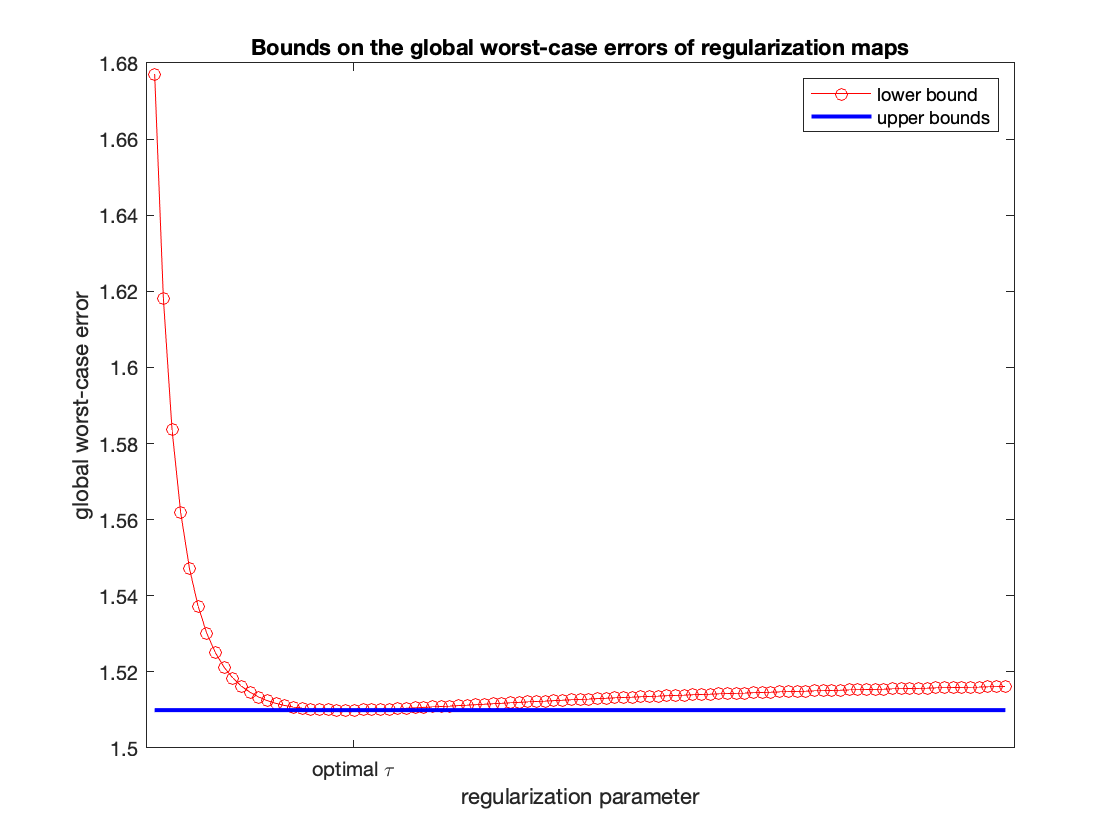

Upper bound and lower bound for global optimal recovery map are 0.4000 and 0.4000, respectively.
They are same, which equal to epsilon 0.4000 as well.

p = plot(range_tau,upper_bound,'ro-',range_tau,lower_bound*ones(1,T),'b-');
set(p,{'LineWidth'},{0.5;2})
legend('lower bound','upper bounds')
title('Bounds on the global worst-case errors of regularization maps')
ylabel('global worst-case error')
xlabel('regularization parameter')
xticks(d/(c+d))
xticklabels('optimal \tau')

## G2: Globally optimal recovery with orthonormal observations

Under the orthonormal observations assumption ($\Lambda\Lambda^*=\mathrm{Id}_{\mathbb{R}^m}$), all the regularization maps $\Delta_\tau$ turn out to be globally optimal.

To illustrate this numerically, we study the global worst-case error $\mathrm{gwce}(\Delta_\tau)$ by computing a lower bound and upper bounds on a grid of values of $\tau \in [0,1]$, as in G1 above, We also compare these values to the theoretical value of the global worst-case error, which is 


$$\mathrm{gwce} = \frac{1-\tau_\#}{\lambda_\#} \varepsilon^2 + \frac{\tau_\#}{\lambda_\#} \eta^2,$$


where $\lambda_\# := \lambda_\min((1-\tau_\#)P_{\mathcal{V}^\perp}+\tau_\#\Lambda^*\Lambda)$ and $\tau_\#$ is the parameter $\tau$ between 1/2 and $\epsilon/(\epsilon+\eta)$that satisfies

$\lambda_\min((1-\tau)P_{\mathcal{V}^\perp}+\tau\Lambda^*\Lambda) = \frac{(1-\tau)^2\epsilon^2-\tau^2\eta^2}{(1-\tau)\epsilon^2-\tau\eta^2}$.

#### Problem setting

We adopt the same problem setting as before.

close all; clear;
N = 50;         
n = 15;                    
V = rand(N,n);            
epsilon = 0.4;           
m = 25;                     
L = randn(m,N);            
L = sqrtm(L*L')\L;          
eta = 0.3;                 
P1 = eye(N) - V*inv(V'*V)*V'; 
P2 = L'*L;
C = L*V;
C_linv = (C'*C)\C';
Delta_0 = V*C_linv;
Delta_1 = L' - L'*C*C_linv + V*C_linv; 

#### Verification that all the bounds coincide with the theoretical value of the global worst-case error

We compute the lower bound first. 

cvx_begin quiet
variable c nonnegative
variable d nonnegative
minimize c*epsilon^2 + d*eta^2
subject to
c*P1 + d*L'*L - eye(N)== semidefinite(N);
cvx_end
lower_bound = sqrt(cvx_optval);

Next, we compute the upper bounds on a grid of values of $\tau\in[0,1]$.

T = 101;
range_tau = linspace(0,1,T);
upper_bound = zeros(1,T);
for idx=1:T
    tau = range_tau(idx);
    Delta_tau = (1-tau)*Delta_0 + tau*Delta_1;
    cvx_begin quiet
    variable c nonnegative
    variable d nonnegative
    minimize c*epsilon^2 + d*eta^2
    subject to
    [ c*P1 - (eye(N)-L'*Delta_tau')*(eye(N)-Delta_tau*L),-(eye(N)-L'*Delta_tau')*Delta_tau;... 
      -Delta_tau'*(eye(N)-Delta_tau*L), d*eye(m)-Delta_tau'*Delta_tau] == semidefinite(N+m);
    cvx_end
    upper_bound(idx) = sqrt(cvx_optval);
end

Finally, we calculate the theoretical value of the global worst-case error and verify that the previous bounds are all equal to this theoretical value.

F = @(t) min(eig((1-t)*P1 + t*P2)) - ((1-t)^2*epsilon^2-t^2*eta^2)/((1-t)*epsilon^2 - t*eta^2);
tau = fzero(F,1/2);
lambda = min(eig((1-tau)*P1 + tau*P2));
gwce = sqrt((1-tau)*epsilon^2/lambda + tau*eta^2/lambda);

fprintf(['The lower bound, upper bounds, and theoretical values are all the same, precisely:\n '...
    'the lower bound equals to %.4f, \n '...
    'the maximal upper bound is %.4f, \n '...
    'and the theoretical value is %.4f.'], lower_bound, max(upper_bound), gwce)

The lower bound, upper bounds, and theoretical values are all the same, precisely:
 the lower bound equals to 2.6644, 
 the maximal upper bound is 2.6644, 
 and the theoretical value is 2.6644.

#### References

- S. Foucart and C. Liao, "Optimal recovery from inaccurate data in Hilbert spaces: regularize, but what of the parameter?", Preprint.

- M. Grant and S. Boyd, "CVX: Matlab software for disciplined convex programming", version 2.1. `http://cvxr.com/cvx`, March 2014.

#### Auxilliary functions used earlier

function [tau,cheb_center,wce] = BE(epsilon,eta,y,P,L)
    N = size(P,1);
    cvx_begin quiet
    variable c nonnegative
    variable d nonnegative
    variable t nonnegative
    minimize epsilon^2*c - (norm(y)^2-eta^2)*d + t
    subject to
    c*P + d*(L'*L) - eye(N) == hermitian_semidefinite(N);
    [c*P+d*(L'*L), -d*L'*y; -d*y'*L, t] == hermitian_semidefinite(N+1);
    cvx_end
    tau = d/(c+d);
    cheb_center = (c*P+d*L'*L)\(d*L'*y);
    wce = sqrt(cvx_optval);
end

function [tau,cheb_center,wce] = BE_real(epsilon,eta,y,P,L)
    N = size(P,1);
    cvx_begin quiet
    variable c nonnegative
    variable d nonnegative
    variable t nonnegative
    minimize epsilon^2*c - (norm(y)^2-eta^2)*d + t
    subject to
    c*P + d*(L'*L) - eye(N) == semidefinite(N);
    [c*P+d*(L'*L), -d*L'*y; -d*y'*L, t] == semidefinite(N+1);
    cvx_end
    tau = d/(c+d);
    cheb_center = (c*P+d*L'*L)\(d*L'*y);
    wce = sqrt(cvx_optval);
end